# Alexnet-like, HRTF-independent

Paweł Antoniuk 2021

Bialystok University of Technology

clear; clc;
rng('default');
inputSize = [349, 150, 4];
inputSpecgramsFile = 'Spectrograms\specgrams-all-lin.h5';

Training params

params.InputSpecgramsFile = inputSpecgramsFile;
params.MaxEpochs = 30;
params.InitialLearnRate = 0.005;
params.MiniBatchSize = 128;

Evaluation loop params

splitStart = 2;
splitStop = 2;

Preview data

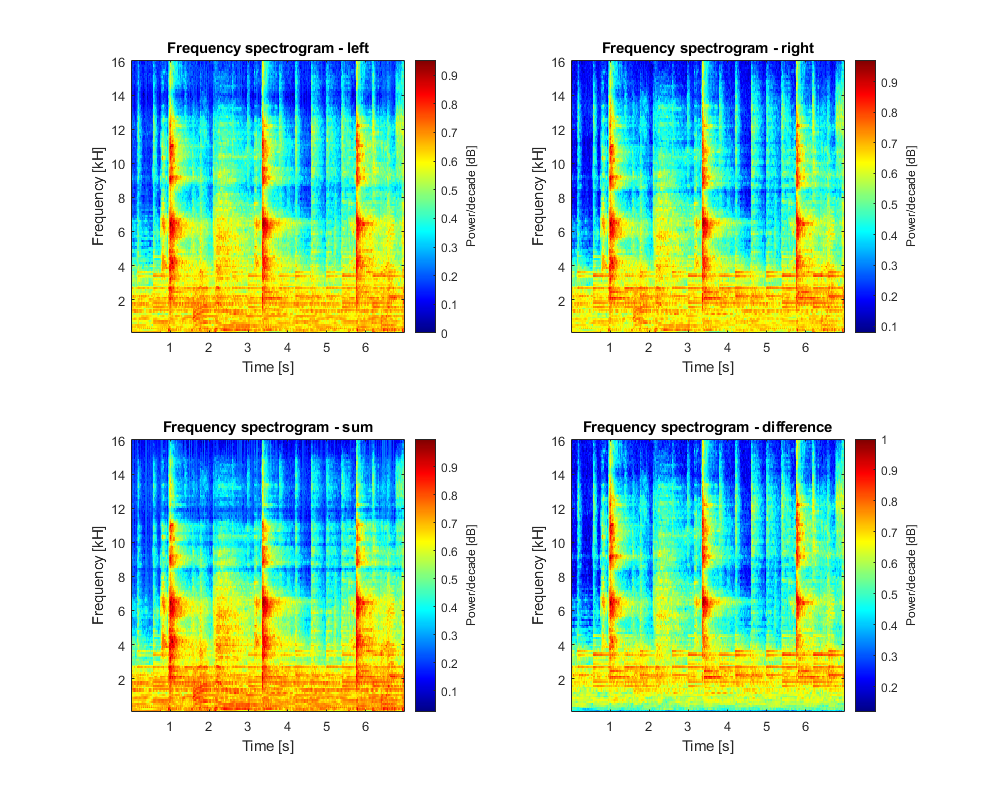

indxSpecgram = 1;
sampleSpecgrams = h5read(inputSpecgramsFile, '/data', ...
    [1, 1, 1, indxSpecgram], [inputSize, 1]);
timeValues = h5read(inputSpecgramsFile, '/axis/time');
freqValues = h5read(inputSpecgramsFile, '/axis/freq');

specNames = {'left', 'right', 'sum', 'difference'};

clf
figure('Position', [0 0 1000 800])
for ii = 1:4
    subplot(2, 2, ii);
    imagesc(timeValues, freqValues / 1000, sampleSpecgrams(:, :, ii)'); 
    colormap jet; 
    axis xy;  
    pbaspect([1 1 1])
    title(['Frequency spectrogram - ', specNames{ii}])
    xlabel('Time [s]')
    ylabel('Frequency [kH]')
    ylabel(colorbar, 'Power/decade [dB]')
end

## Model training

rng('default');

Load dataset and metdata

dsFilenames = h5read(params.InputSpecgramsFile, '/filenames');
[songNames, HRTFs, HRTFGroups] = getSongNamesHRTFsGroups(dsFilenames);
uniqueHRTFNames = unique(HRTFs);
uniqueHRTFGroupNames = unique(HRTFGroups);
ds = H5MatrixDatastore(params.InputSpecgramsFile, '/data', '/labels');

Split dataset into training and test dataset by song names in 'train recordings.csv' and 'test recordings.csv'

nSplits = splitStop - splitStart + 1;
splitsResults = cell(1, nSplits);
for iSplit = splitStart:splitStop
iSplit
splitTic = tic;

Select only a subset of training and test data. Selection is made for each HRTF group name (aachen, mti, etc.) so training dataset contains all HRTF group names except the specific one and test data contains only the specified HRTF group name.

HRTFGroupsResults = containers.Map();
for iHRTFGroup = 1:length(uniqueHRTFGroupNames)
currentSelectedHRTFGroup = uniqueHRTFGroupNames{iHRTFGroup}
restHRTFGroups = setdiff(uniqueHRTFGroupNames, currentSelectedHRTFGroup);

### Data preparation

Splits are predefinied in the csv files

trainRecordings = readtable('train recordings.csv', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');
testRecordings = readtable('test recordings.csv', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');

currentTrainingRecordings = trainRecordings{:, iSplit};
currentTestRecordings = testRecordings{:, iSplit};

trainDs = ds.filterDs(@(ii) any(strcmp(songNames(ii), currentTrainingRecordings)));
trainDs = trainDs.filterDs(@(ii) any(strcmp(HRTFGroups(ii), restHRTFGroups)));

testDs = ds.filterDs(@(ii) any(strcmp(songNames(ii), currentTestRecordings))); 
testDs = testDs.filterDs(@(ii) any(strcmp(HRTFGroups(ii), currentSelectedHRTFGroup)));

### Checking

Check if trainDs + valDs and testDs have distinct song names (empty arrays excepted)

assert(numel(intersect(unique(dsFilenames(trainDs.IndexValues)), unique(dsFilenames(testDs.IndexValues)))) == 0);
assert(numel(intersect(unique(songNames(trainDs.IndexValues)), unique(songNames(testDs.IndexValues)))) == 0);
assert(numel(intersect(unique(HRTFGroups(trainDs.IndexValues)), unique(HRTFGroups(testDs.IndexValues)))) == 0);

Load layers

layers = [
    imageInputLayer(inputSize,"Name","imageinput", 'Normalization',"none")
    convolution2dLayer([3 3],16,"Name","conv_1")
    reluLayer("Name","relu_1")
    batchNormalizationLayer("Name","batchnorm_1")
    
    maxPooling2dLayer([3 2],"Name","maxpool_1","Stride",[3 2])
    
    convolution2dLayer([3 3],32,"Name","conv_2")
    reluLayer("Name","relu_2")
    batchNormalizationLayer("Name","batchnorm_2")
    
    maxPooling2dLayer([3 2],"Name","maxpool_2","Stride",[3 2])
    
    convolution2dLayer([3 3],64,"Name","conv_3")
    reluLayer("Name","relu_3")
    batchNormalizationLayer("Name","batchnorm_3")
    
    maxPooling2dLayer([2 2],"Name","maxpool_3","Stride",[2 2])
    
    convolution2dLayer([3 3],128,"Name","conv_4")
    reluLayer("Name","relu_4")
    batchNormalizationLayer("Name","batchnorm_4")
    
    maxPooling2dLayer([2 2],"Name","maxpool_4","Stride",[2 2])
    
    convolution2dLayer([3 3],256,"Name","conv_5")
    reluLayer("Name","relu_5")    
    batchNormalizationLayer("Name","batchnorm_5")
    
    dropoutLayer(0.5,"Name","dropout_1")
    fullyConnectedLayer(64,"Name","fc_1")
    reluLayer("Name","relu_6")    
    
    dropoutLayer(0.5,"Name","dropout_2")
    fullyConnectedLayer(32,"Name","fc_2")
    reluLayer("Name","relu_7")    
    
    dropoutLayer(0.5,"Name","dropout_3")
    fullyConnectedLayer(16,"Name","fc_3")
    reluLayer("Name","relu_8")    
    
    dropoutLayer(0.5,"Name","dropout_4")
    fullyConnectedLayer(2,"Name","fc_4")
    softmaxLayer('Name', 'softmax')
    
    classificationLayer('Name', 'output')];

Training options

options = trainingOptions('adam', ...
    'MaxEpochs', params.MaxEpochs, ...
    'InitialLearnRate', params.InitialLearnRate, ...
    'MiniBatchSize', params.MiniBatchSize, ...
    'Shuffle', 'every-epoch', ...
    'VerboseFrequency', 1000, ...
    'Plots',"training-progress", ...
    'ValidationFrequency', 50, ...
    'LearnRateSchedule', 'piecewise', ...
	'LearnRateDropPeriod', 5, ...
	'LearnRateDropFactor', 0.5, ...
    'ValidationData', testDs);

Training loop

[net, info] = trainNetwork(trainDs, layers, options);
% nLearnableParams = countLearnableParams(net)

### Evaulate performance

Evaluate performacne on the training set

preds = classify(net, trainDs);
targets = trainDs.Labels(trainDs.IndexValues);
trainAccuracy = nnz(preds == targets) / length(trainDs.IndexValues)

Evaluate performance on the test set

preds = classify(net, testDs);
targets = testDs.Labels(testDs.IndexValues);
testAccuracy = nnz(preds == targets) / length(testDs.IndexValues)

Save the HRTF group results

results.net = net;
results.info = info;
results.trainAccuracy = trainAccuracy;
results.testAccuracy = testAccuracy;
HRTFGroupsResults(currentSelectedHRTFGroup) = results;

Save the split results

outputFilename = sprintf('lmpa2i_partial_results/partial_results_inhrtf %s', datestr(clock, 'HHMMSS'));
save(outputFilename, '-v7.3')

end % end % for iHRTFGroup
splitsResults{iSplit} = HRTFGroupsResults;

outputFilename = sprintf('lmpa2i_partial_results/partial_results_insplit %s', datestr(clock, 'HHMMSS'));
save(outputFilename, '-v7.3')

toc(splitTic)
end % end % for iSplit

iSplit = 2

currentSelectedHRTFGroup = 'aachen'

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       47.66% |       56.88% |       1.8425 |       1.0499 |          0.0050 |
|       1 |          50 |       00:00:56 |       53.91% |       54.37% |       0.6882 |       0.6924 |          0.0050 |
|       1 |         100 |       00:01:44 |       60.16% |       58.75% |       0.6755 |       0.6840 |          0.0050 |
|       2 |         150 |       00:02:36 |       67.97% |       74.38% |       0.5820 |       0.6303 |          0.0050 |
|       

trainAccuracy = 1

testAccuracy = 0.9625

currentSelectedHRTFGroup = 'ari'

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |       53.12% |       53.39% |       1.7004 |       0.7549 |          0.0050 |
|       1 |          50 |       00:01:27 |       57.81% |       51.25% |       0.6972 |       0.6926 |          0.0050 |
|       1 |         100 |       00:02:34 |       53.91% |       49.46% |       0.6987 |       0.6932 |          0.0050 |
|       2 |         150 |       00:03:44 |       56.25% |       61.07% |       0.6846 |       0.6813 |          0.0050 |
|       

trainAccuracy = 1

testAccuracy = 0.9750

currentSelectedHRTFGroup = 'cipic'

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       54.69% |       53.57% |       0.9998 |       0.7168 |          0.0050 |
|       1 |          50 |       00:01:14 |       51.56% |       50.54% |       0.7061 |       0.6948 |          0.0050 |
|       1 |         100 |       00:02:21 |       58.59% |       63.21% |       0.6804 |       0.6774 |          0.0050 |
|       2 |         150 |       00:03:30 |       58.59% |       73.93% |       0.6448 |       0.6276 |          0.0050 |
|       

trainAccuracy = 1

testAccuracy = 0.8482

currentSelectedHRTFGroup = 'clubfritz'

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |       52.34% |       56.96% |       1.8393 |       0.8069 |          0.0050 |
|       1 |          50 |       00:01:37 |       57.81% |       53.39% |       0.6966 |       0.6918 |          0.0050 |
|       1 |         100 |       00:03:00 |       57.81% |       73.39% |       0.6805 |       0.6861 |          0.0050 |
|       2 |         150 |       00:04:36 |       60.16% |       66.25% |       0.6731 |       0.6842 |          0.0050 |
|       

trainAccuracy = 1

testAccuracy = 0.9232

currentSelectedHRTFGroup = 'hutubs'

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |       43.75% |       52.50% |       1.4674 |       0.7054 |          0.0050 |
|       1 |          50 |       00:01:42 |       47.66% |       50.36% |       0.7478 |       0.6927 |          0.0050 |
|       1 |         100 |       00:03:11 |       53.12% |       52.50% |       0.7282 |       0.6906 |          0.0050 |
|       2 |         150 |       00:05:01 |       62.50% |       59.82% |       0.6404 |       0.6727 |          0.0050 |
|       

trainAccuracy = 1

testAccuracy = 0.8911

currentSelectedHRTFGroup = 'listen'

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:17 |       48.44% |       45.71% |       1.0882 |       0.7395 |          0.0050 |
|       1 |          50 |       00:01:50 |       55.47% |       50.18% |       0.6981 |       0.6938 |          0.0050 |
|       1 |         100 |       00:03:24 |       53.91% |       56.43% |       0.6740 |       0.6754 |          0.0050 |
|       2 |         150 |       00:05:37 |       66.41% |       76.25% |       0.6480 |       0.5776 |          0.0050 |
|       

trainAccuracy = 1

testAccuracy = 0.9393

currentSelectedHRTFGroup = 'mit'

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |       55.47% |       48.75% |       1.5726 |       0.9086 |          0.0050 |
|       1 |          50 |       00:01:59 |       57.81% |       62.50% |       0.6754 |       0.6895 |          0.0050 |
|       1 |         100 |       00:03:48 |       64.06% |       71.25% |       0.6965 |       0.6497 |          0.0050 |
|       2 |         150 |       00:06:00 |       68.75% |       74.38% |       0.6690 |       0.6273 |          0.0050 |
|       

trainAccuracy = 1

testAccuracy = 0.9625

currentSelectedHRTFGroup = 'riec'

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |       47.66% |       56.07% |       2.5347 |       0.7326 |          0.0050 |
|       1 |          50 |       00:02:13 |       50.00% |       57.68% |       0.7288 |       0.6891 |          0.0050 |
|       1 |         100 |       00:04:08 |       65.62% |       70.18% |       0.6520 |       0.6443 |          0.0050 |
|       2 |         150 |       00:06:35 |       67.19% |       66.25% |       0.6632 |       0.5804 |          0.0050 |
|       

Save workspace

outputFilename = sprintf('lmpa2i_results/results %s', datestr(clock, 'HHMMSS'));
save(outputFilename, '-v7.3')

Save to xls

outputTable = table('Size', [length(uniqueHRTFGroupNames) 7], ...
    'VariableTypes', repmat({'double'}, 1, 7), ...
    'VariableNames', cellstr(num2str((0:6)')), ...
    'RowNames', uniqueHRTFGroupNames);
outputTable.Properties.DimensionNames{1} = ' ';

for iSplit = splitStart:splitStop
    HRTFGroupsResultsKeys = keys(splitsResults{iSplit});
    HRTFGroupsResultsValues = values(splitsResults{iSplit});
    
    for iHRTFGroup = 1:length(HRTFGroupsResultsKeys)
        outputTable{iHRTFGroup, iSplit} = HRTFGroupsResultsValues{iHRTFGroup}.testAccuracy;
    end
end

writetable(outputTable, [outputFilename '.xls'], ...
    'WriteVariableNames', true, ...
    'WriteRowNames',true);